## Definición de Problema

clear;
CostFunction = @(x) sum(x.^2, 2);       % Función de costo a optimizar
VarDims = 2;                            % No. Variables desconocidas (Varibles de decisión). Dims de posición de partículas

PosMin = -10;                           % Límite inferior para el valor de las variables desconocidas
PosMax = 10;                            % Límite superior para el valor de las variables desconocidas.

VelMax = 0.2*(PosMax - PosMin);         % Velocidad máxima es un 20% de la diferencia en posiciones
VelMin = -VelMax;                       % Velocidad mínima es solo el negativo de la máxima

[MeshX, MeshY] = meshgrid(PosMin:PosMax, PosMin:PosMax);
Mesh2D = [reshape(MeshX, [], 1) reshape(MeshY, [], 1)];                     % MeshX y MeshY se convierten en vectores columna y se concatenan
Altura = reshape(CostFunction(Mesh2D), size(MeshX, 1), size(MeshX, 2));     % Evalúa cada fila de Mesh2D en "CostFunction". Luego convierte los resultados en una matriz del tamaño de MeshX
MaxAltura = max(max(Altura));                                               % Se obtiene dos veces el "max" para sacar el máximo de todas las columnas, luego el de todas las filas.

X1_min = min(min(Altura,[],2));         % Valor mínimo X1 = Eje X de la matriz de alturas
X2_min = min(min(Altura,[],1));         % Valor mínimo X2 = Eje Y de la matriz de alturas
Coords_Min = [X1_min X2_min];

AreaTotal = (PosMax - PosMin)^2;        % Se obtiene el área total donde se podrán mover las partículas
Porcentaje_AreaTotal = 0.1;             % Area de convergencia = Porcentaje del área total
RadioConvergencia = sqrt((AreaTotal * (Porcentaje_AreaTotal/100)) / pi);    % Radio de convergencia (Suponiendo área circular) = Despejar para el radio de un círculo en la fórmula para el área   


## Parámetros PSO

NoParticulas = 50;                              % No. de partículas
Colores = (1: NoParticulas) / NoParticulas;     % Vector con los colores de cada punto

% Coeficientes de Constricción
Kappa = 1;
Phi1 = 2.05;
Phi2 = 2.05;

% Variación de los parámetros propuestos en el paper de Clerc y Kennedy
Intervalo = 25;
VecKappa = 0 : Kappa*2 / (Intervalo-1)  : Kappa*2;                      % Vector con "Intervalo" valores entre 0 y 2*Kappa 
VecPhi1 = 0 : Phi1*2 / (Intervalo-1) : Phi1*2;                          % Vector con "Intervalo" valores entre 0 y 2*Phi1
VecPhi2 = 0 : Phi2*2 / (Intervalo-1) : Phi2*2;                          % Vector con "Intervalo" valores entre 0 y 2*Phi2

[MatPhi1, MatPhi2, MatKappa] = meshgrid(VecPhi1, VecPhi2, VecKappa);    % Meshgrid con todos los valores posibles de Phi1, Phi2 y Kappa
MatPhi1 = reshape(MatPhi1,[], 1);                                       % Se convierten todos los "Mesh" en vectores columna
MatPhi2 = reshape(MatPhi2,[], 1);
MatKappa = reshape(MatKappa,[], 1);

Points = size(MatKappa, 1);                                             % Número de filas de Kappa. Esto es igual al número de puntos (Phi1, Phi2, Kappa) a evaluar

## Main Loop

ModoVisualizacion = "None";                                             % Modo de visualización: 2D, 3D o None. Default = 3D

Iteraciones_History = zeros(Points,1);                                  % "Iteraciones_History": Iteraciones requeridas para converger en cada variación de parámetros

if strcmp(ModoVisualizacion, "None") == 0                               % Si el modo de visualización es ajeno a "None"
    figure(1); clf;                                                     
    figure('visible','on');                                             % Utilizado para que la animación se despliegue en un .mlx
    axis equal; grid on; 
    
    FigureWidth = 900;                                                  % Se desea que la figura sea de 900 x 400 px.
    FigureHeight = 400;
    ScreenSize = get(0,'ScreenSize');                                   % Se obtiene el tamaño de la pantalla actual
    
    set(gcf, 'Position',  [ScreenSize(3)/2 - FigureWidth/2, ScreenSize(4)/2 - FigureHeight/2, FigureWidth, FigureHeight])
end

for j = 1:Points                                                       
    
    % Variación en los parámetros del algoritmo.
    % Basado en el paper publicado por Clerc y Kennedy (2002)
    
    Phi1 = MatPhi1(j);                                                  % Phi1 = Fila "j" de MatPhi1
    Phi2 = MatPhi2(j);                                                  % Phi2 = Fila "j" de MatPhi2
    Kappa = MatKappa(j);                                                % Kappa = Fila "j" de Kappa

    Phi = Phi1 + Phi2;                                                  
    Chi = 2*Kappa / abs(2 - Phi - sqrt(Phi^2 - 4*Phi));

    W = Chi;                                                            % Coeficiente de inercia.
    WDamp = 1;                                                          % Coeficiente de amortiguamiento del coeficiente inercial
    C1 = Chi*Phi1;                                                      % Coeficiente de aceleración local (Personal)
    C2 = Chi*Phi2;                                                      % Coeficiente de aceleración global
    
    Iteraciones = 1;
    
    % Inicialización de parámetros para la simulación
    
    IteracionesMax = 3000;                                                  % Iteraciones máximas para converger
    Posicion_Actual = unifrnd(PosMin, PosMax, [NoParticulas VarDims]);      % Posición (Random) de todas las partículas. Distribución uniforme.     Dims: NoParticulas X VarDims
    Posicion_LocalBest = Posicion_Actual;                                   % Las posiciones que generaron los mejores costos en las partículas     Dims: NoParticulas X VarDims
    Velocidad = zeros([NoParticulas VarDims]);                              % Velocidad de todas las partículas. Inicialmente 0.                    Dims: NoParticulas X VarDims
    Costo_Local = CostFunction(Posicion_Actual);                            % Evaluación del costo en la posición actual de la partícula.           Dims: NoPartículas X 1 (Vector Columna)
    Costo_LocalBest = Costo_Local;
    
    [Costo_GlobalBest, Fila] = min(Costo_LocalBest);                        % "Global best": El costo más pequeño del vector "CostoLocal"           Dims: Escalar
    Posicion_GlobalBest = Posicion_Actual(Fila, :);                         % "Global best": Posición que genera el costo más pequeño               Dims: 1 X VarDims
    
    Costo_History = zeros([IteracionesMax 1]);                              % Historial de todos los "Costo_Global" o global best
    Costo_History(1) = Costo_GlobalBest;                                    % La primera posición del vector es el primer "Global Best"
    
    % Corrida del algoritmo de PSO.
    % Se toma nota del número de iteraciones requeridas.
    for i = 2:IteracionesMax
        
        R1 = rand([NoParticulas VarDims]);                                              % R1 y R2: Valores aleatorios normalmente distribuidos
        R2 = rand([NoParticulas VarDims]);
        
        % Actualización de Velocidad
        Velocidad = W * Velocidad ...                                                   % Término inercial
            + C1 * R1 .* (Posicion_LocalBest - Posicion_Actual) ...                     % Componente cognitivo
            + C2 * R2 .* (Posicion_GlobalBest - Posicion_Actual);                       % Componente social
        
        Velocidad = max(Velocidad, VelMin);                                             % Se truncan los valores de velocidad en el valor mínimo y máximo
        Velocidad = min(Velocidad, VelMax);
        
        % Actualización de Posición
        Posicion_Actual = Posicion_Actual + Velocidad;
        Posicion_Actual = max(Posicion_Actual, PosMin);                                 % Se truncan los valores de posición en el valor mínimo y máximo
        Posicion_Actual = min(Posicion_Actual, PosMax);
        
        % Actualización de Local y Global Best
        Costo_Local = CostFunction(Posicion_Actual);                                    % Actualización de los valores del costo
        Costo_LocalBest = min(Costo_LocalBest, Costo_Local);                            % Se sustituyen los costos que son menores al "Local Best" previo
        Costo_Change = (Costo_Local < Costo_LocalBest);                                 % Vector binario que indica con un 0 cuales son las filas de "Costo_Local" que son menores que las filas de "Costo_LocalBest"
        Posicion_LocalBest = Posicion_LocalBest .* Costo_Change + Posicion_Actual;      % Se sustituyen las posiciones correspondientes a los costos a cambiar en la linea previa
        
        [Costo_Global, Fila] = min(Costo_LocalBest);                                    % Valor mínimo de entre los valores de "Costo_Local"
        
        if Costo_Global < Costo_GlobalBest                                              % Si el nuevo costo global es menor al "Global Best" entonces
            Costo_GlobalBest = Costo_Global;                                            % Se actualiza el valor del "Global Best"
            Posicion_GlobalBest = Posicion_Actual(Fila, :);                             % Y la posición correspondiente al "Global Best"
        end
        
        % Actualización del historial de "Best Costs"
        Costo_History(i) = Costo_GlobalBest;                                            
        
        % Actualización del coeficiente inercial
        W = W * WDamp;
        
        % Actualizar el número de iteraciones
        Iteraciones = Iteraciones + 1;
        
        if strcmp(ModoVisualizacion, "None") == 0 
            
            % Graficación de partículas
            subplot(1, 2, 2); cla;
            
            if strcmp(ModoVisualizacion, "2D")                                                              % Modo 2D
                axis([PosMin PosMax PosMin PosMax]);
                contour(MeshX, MeshY, Altura);                                                              % Gráfica: Niveles de la superficie que describe la función de costo.
                scatter(Posicion_Actual(:,1), Posicion_Actual(:,2), 10, Colores, 'filled');                 % Gráfica: Posición actual de todos los puntos
                scatter(X1_min, X2_min, 'red', 'x');                                                        % Gráfica: Mínimo del campo vectorial
                viscircles([X1_min X2_min], RadioConvergencia);                                             % Gráfica: Círculo o área de convergencia
                
            else                                                                                            % Modo 3D
                axis([PosMin PosMax PosMin PosMax 0 MaxAltura]);                                
                surf(MeshX, MeshY, Altura);                                                                 % Gráfica: Superficie a minimizar utilizando función de costo.
                shading interp; alpha 0.5;                                                                  % Gráfica semi transparente y con gradiente suave en la coloración
                scatter3(Posicion_Actual(:,1), Posicion_Actual(:,2), Costo_Local, [], Colores, 'filled');   % Gráfica: Partículas
            end
            title({"Partículas"; strcat("Radio Convergencia: ", num2str(RadioConvergencia), " (", num2str(Porcentaje_AreaTotal), "%)")});
            hold on;
            
            % Graficación dinámica de la minimización de la función de costo
            subplot(1, 2, 1); cla;
            plot(Costo_History(1:i), 'LineWidth', 2);
            title({"Minimización de Función de Costo" ; strcat("Iteraciones Actuales: ", num2str(i))})
            xlabel('Iteración');
            ylabel('Costo Óptimo');
            
            % Actualización de los plots
            drawnow
            
        end
        
        
        Distancia_ParticulaMasLejana = max(sqrt(sum((Posicion_Actual - Coords_Min).^2, 2)));                % Se calculan las distancias de todas las partículas al mínimo del plano. Luego se obtiene el máximo.
        
        % Criterios de finalización
        % 1. Si la distancia de la partícula más lejana al mínimo es menor al radio de convergencia
        % 2. Si se ha alcanzado el número máximo de iteraciones.
        if (Distancia_ParticulaMasLejana < RadioConvergencia) || (i == IteracionesMax)                      
            Iteraciones = i;
            
            if strcmp(ModoVisualizacion, "None") == 0
                title({"Minimización de Función de Costo" ; strcat("Iteraciones para Converger: ", num2str(Iteraciones))});
            end
            
            break
        end
        
    end
    
    Iteraciones_History(j) = Iteraciones;
    
end

disp("Proceso Finalizado")

Proceso Finalizado


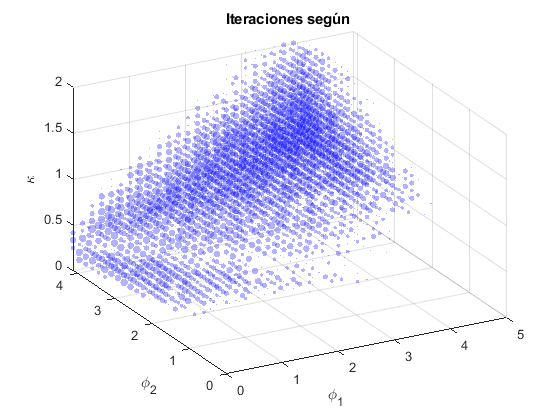

load Iteraciones.mat
IteracionesMax = 3000;

Iteraciones_HistoryNorm = 1 - (Iteraciones_History/IteracionesMax);
IterMax = max(nonzeros(Iteraciones_HistoryNorm));
IterMin = min(nonzeros(Iteraciones_HistoryNorm));
Threshold = 0.998 * (IterMax - IterMin) + IterMin;

FilteredMin = min(Iteraciones_HistoryNorm(Iteraciones_HistoryNorm > Threshold));
FilteredMax = max(Iteraciones_HistoryNorm(Iteraciones_HistoryNorm > Threshold) - FilteredMin);

FilteredIter = (Iteraciones_HistoryNorm(Iteraciones_HistoryNorm > Threshold) - FilteredMin) / FilteredMax;
FilteredPhi1 = MatPhi1(Iteraciones_HistoryNorm > Threshold);
FilteredPhi2 = MatPhi2(Iteraciones_HistoryNorm > Threshold);
FilteredKappa = MatKappa(Iteraciones_HistoryNorm > Threshold);

BaseInterval = [0 1];
NewInterval = [1 40];

Remap = @(X, XBase, XNew) floor(XNew(1) + (X - XBase(1)) * (XNew(2) - XNew(1)) / (XBase(2) - XBase(1)));

FilteredIter = Remap(FilteredIter, BaseInterval, NewInterval);

figure(1); clf;
%figure('visible','on');
axis equal; grid on;
axis([min(MatPhi1) max(MatPhi1) min(MatPhi2) max(MatPhi2) min(MatKappa) max(MatKappa)])

scatter3(FilteredPhi1, FilteredPhi2, FilteredKappa, FilteredIter,'blue','filled');
alpha 0.3;

xlabel("\phi_1");
ylabel("\phi_2");
zlabel("\kappa");
Porcentaje = size(Iteraciones_History,1)/10;
title("Iteraciones según ");